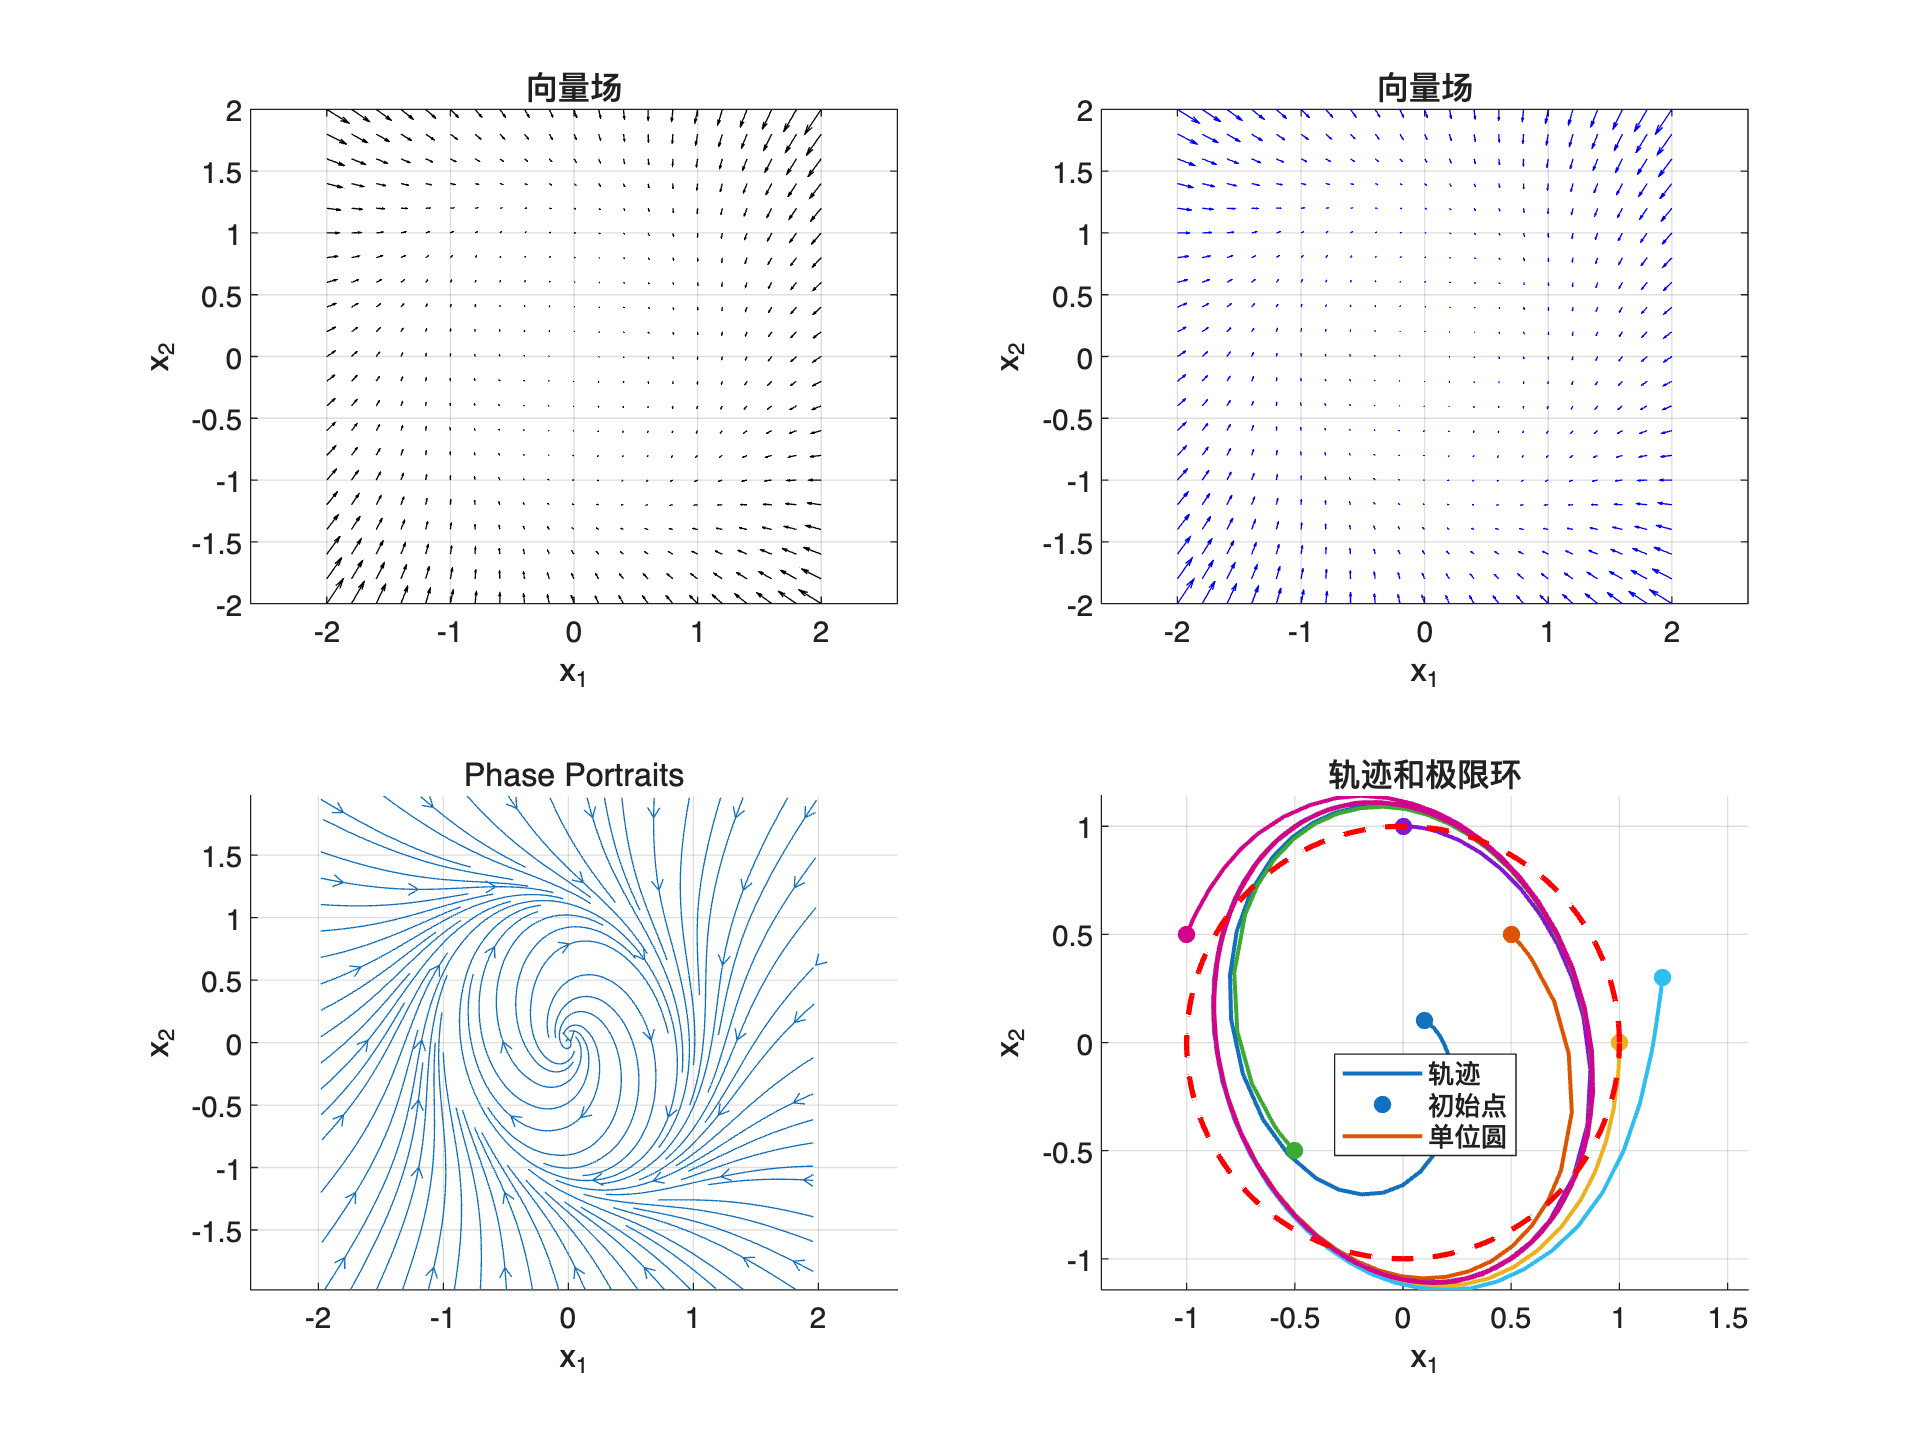

% 清除环境
clear; clc; close all;

% 定义系统方程
dx = @(x) [x(1) + x(2) - x(1)*(x(1)^2 + x(2)^2);
           -2*x(1) + x(2) - x(2)*(x(1)^2 + x(2)^2)];

% 创建网格
[x1, x2] = meshgrid(-2:0.2:2, -2:0.2:2);

% 计算向量场
u = zeros(size(x1));
v = zeros(size(x2));

for i = 1:size(x1,1)
    for j = 1:size(x1,2)
        dx_val = dx([x1(i,j); x2(i,j)]);
        u(i,j) = dx_val(1);
        v(i,j) = dx_val(2);
    end
end

% 计算向量场的模长（用于颜色映射）
speed = sqrt(u.^2 + v.^2);

% 创建图形
figure('Position', [100, 100, 1200, 900]);

% 绘制向量场
subplot(2,2,1);
quiver(x1, x2, u, v, 'k');
xlabel('x_1');
ylabel('x_2');
title('向量场');
axis equal;
grid on;

% 绘制带颜色映射的向量场
subplot(2,2,2);
h = quiver(x1, x2, u, v);
set(h, 'Color', 'b');
xlabel('x_1');
ylabel('x_2');
title('向量场');
axis equal;
grid on;

% 绘制流线
subplot(2,2,3);
streamslice(x1, x2, u, v);
xlabel('x_1');
ylabel('x_2');
title('Phase Portraits');
axis equal;
grid on;

% 模拟多条轨迹
subplot(2,2,4);
hold on;

% 定义不同的初始条件
initial_conditions = [
    0.1, 0.1;
    0.5, 0.5;
    1.0, 0.0;
    0.0, 1.0;
    -0.5, -0.5;
    1.2, 0.3;
    -1.0, 0.5
];

% 颜色映射
colors = lines(size(initial_conditions, 1));

% 模拟每条轨迹
for i = 1:size(initial_conditions, 1)
    [t, x] = ode45(@(t,x) dx(x), [0, 20], initial_conditions(i,:));
    plot(x(:,1), x(:,2), 'Color', colors(i,:), 'LineWidth', 1.5);
    plot(initial_conditions(i,1), initial_conditions(i,2), 'o', ...
         'Color', colors(i,:), 'MarkerFaceColor', colors(i,:));
end

% 绘制极限环（单位圆）
theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), 'r--', 'LineWidth', 2, 'DisplayName', '单位圆');

xlabel('x_1');
ylabel('x_2');
title('轨迹和极限环');
legend('轨迹', '初始点', '单位圆', 'Location', 'best');
axis equal;
grid on;
hold off;

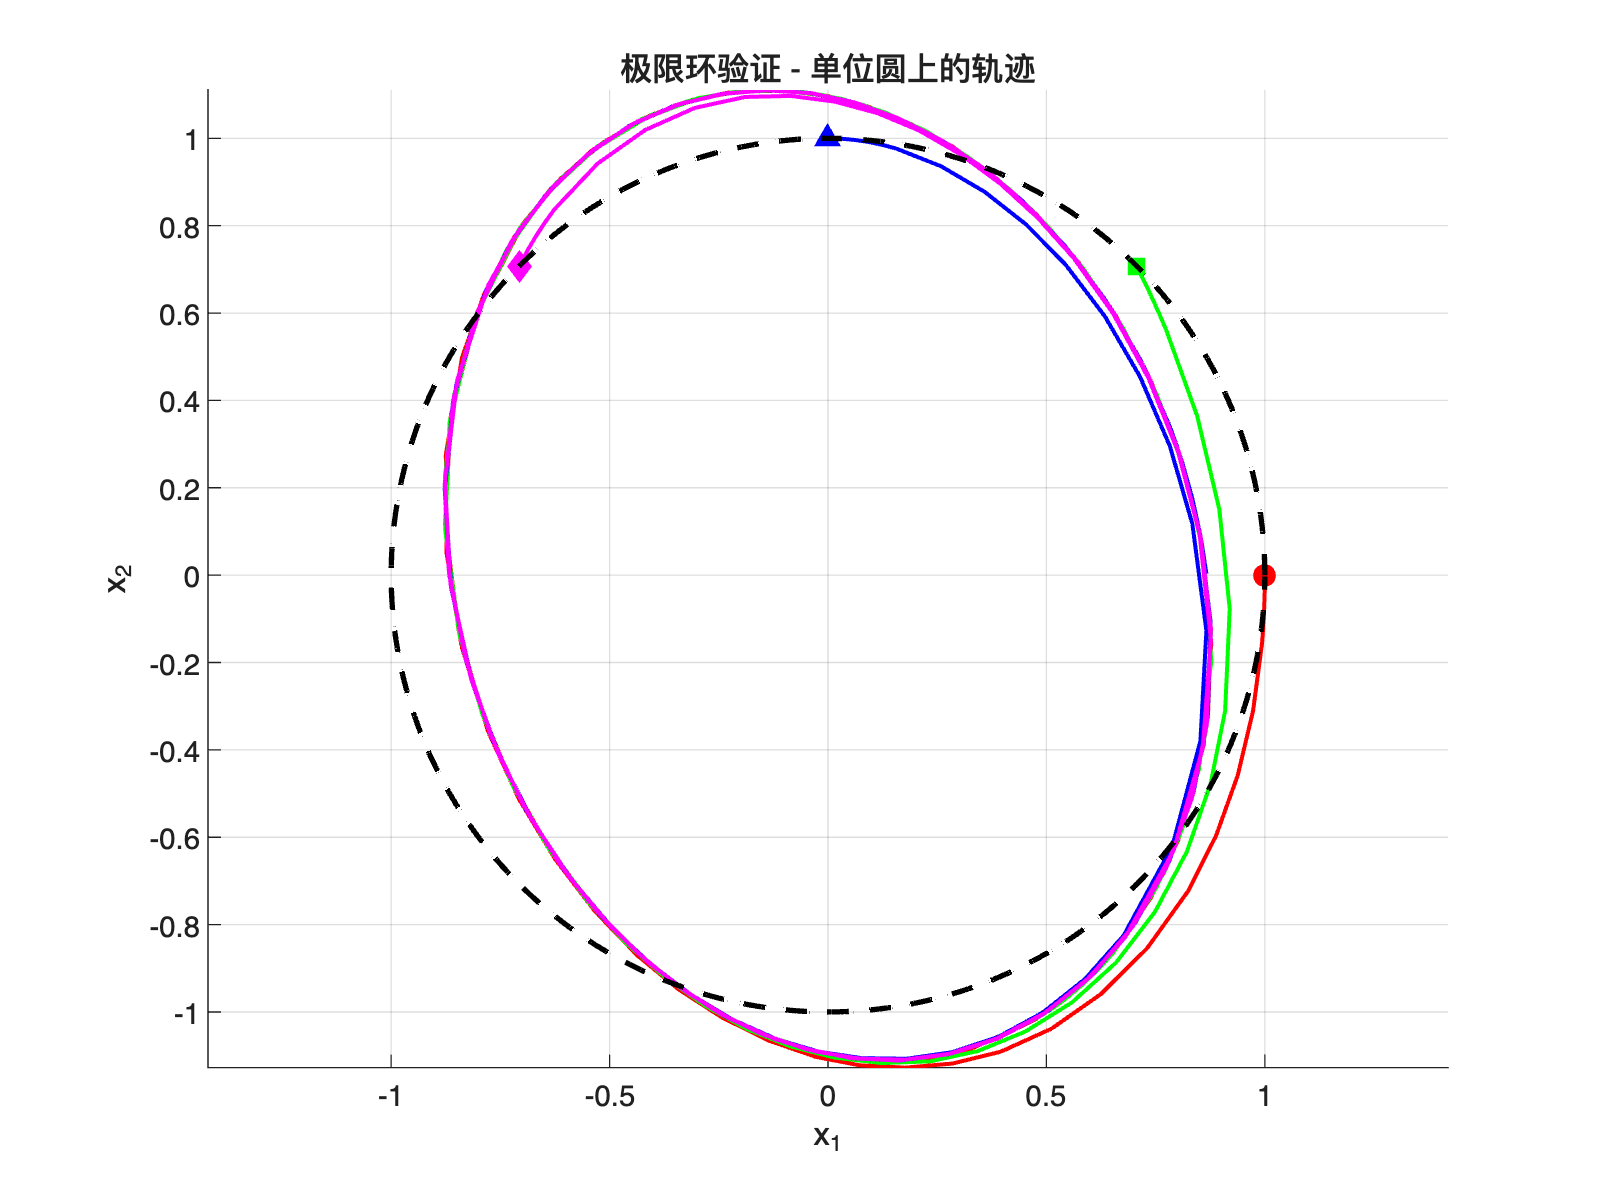


% 创建单独的图形显示极限环验证
figure('Position', [100, 100, 800, 600]);

% 验证单位圆是否为周期轨道
hold on;

% 在单位圆上取几个点验证
theta_test = [0, pi/4, pi/2, 3*pi/4];
colors_test = ['r', 'g', 'b', 'm'];
markers = ['o', 's', '^', 'd'];

for i = 1:length(theta_test)
    x0 = [cos(theta_test(i)); sin(theta_test(i))];
    [t, x] = ode45(@(t,x) dx(x), [0, 10], x0);
    
    % 绘制轨迹
    plot(x(:,1), x(:,2), 'Color', colors_test(i), 'LineWidth', 1.5);
    plot(x0(1), x0(2), markers(i), 'Color', colors_test(i), ...
         'MarkerFaceColor', colors_test(i), 'MarkerSize', 8);
end

% 绘制单位圆
theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 2, 'DisplayName', '单位圆');

xlabel('x_1');
ylabel('x_2');
title('极限环验证 - 单位圆上的轨迹');
axis equal;
grid on;


% 计算并显示在单位圆上的导数
fprintf('在单位圆上验证系统行为:\n');

在单位圆上验证系统行为:


fprintf('θ\t\tx1\t\tx2\t\tdx1/dt\t\tdx2/dt\t\t径向分量\n');

θ		x1		x2		dx1/dt		dx2/dt		径向分量



for i = 1:length(theta_test)
    x1_val = cos(theta_test(i));
    x2_val = sin(theta_test(i));
    dx_val = dx([x1_val; x2_val]);
    
    % 计算径向分量
    radial_component = x1_val*dx_val(1) + x2_val*dx_val(2);
    
    fprintf('%.2f\t%.4f\t%.4f\t%.4f\t%.4f\t%.6f\n', ...
            theta_test(i), x1_val, x2_val, dx_val(1), dx_val(2), radial_component);
end

0.00	1.0000	0.0000	0.0000	-2.0000	0.000000
0.79	0.7071	0.7071	0.7071	-1.4142	-0.500000
1.57	0.0000	1.0000	1.0000	-0.0000	-0.000000
2.36	-0.7071	0.7071	0.7071	1.4142	0.500000



% 添加极坐标验证
fprintf('\n极坐标验证:\n');


极坐标验证:


fprintf('在单位圆上 (r=1):\n');

在单位圆上 (r=1):



% 转换为极坐标验证
syms r theta_sym real
x1_sym = r*cos(theta_sym);
x2_sym = r*sin(theta_sym);

dx1_sym = x1_sym + x2_sym - x1_sym*(x1_sym^2 + x2_sym^2);
dx2_sym = -2*x1_sym + x2_sym - x2_sym*(x1_sym^2 + x2_sym^2);

% 在r=1时计算
dx1_r1 = simplify(subs(dx1_sym, r, 1));
dx2_r1 = simplify(subs(dx2_sym, r, 1));

fprintf('dx1/dt = %s\n', char(dx1_r1));

dx1/dt = sin(theta_sym)


fprintf('dx2/dt = %s\n', char(dx2_r1));

dx2/dt = -2*cos(theta_sym)



% 计算径向速度
radial_velocity_sym = x1_sym*dx1_sym + x2_sym*dx2_sym;
radial_velocity_r1 = simplify(subs(radial_velocity_sym, r, 1));
fprintf('径向速度分量 (在r=1时): %s\n', char(radial_velocity_r1));

径向速度分量 (在r=1时): -sin(2*theta_sym)/2
